# Toxic Conversations Dataset

## Setup

clc;
clear all;
close all;
rng(1634256, "twister");

addpath(genpath(fileparts(which(mfilename))));

## Load Data

% Import the data
rawData = parquetread("./datasets/toxic_conversations_50k/toxic_conversations_50k_all-mpnet-base-v2.parquet", "SelectedVariableNames", ["text", "label_text", "embedding"]);

rawData.label_text = categorical(rawData.label_text);

rawData(1:8, :)

ans = 8×3 table
                                                                                                                                                                                                                                                                                       text                                                                                                                                                                                                                                                                                       label_text      embedding   
    __________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________

groupcounts(rawData, "label_text")

ans = 2×3 table
    label_text    GroupCount    Percent
    __________    __________    _______

    not toxic       46035        92.07 
    toxic            3965         7.93 


## Preperation

sampleSize = 2000;
contamination =0.2;
nonToxicIndices = find(rawData.label_text == "not toxic");
toxicIndices = find(rawData.label_text == "toxic");

numToxicSamples = round(contamination * sampleSize);
numNonToxicSamples = sampleSize - numToxicSamples;

toxicSampleIndices = datasample(toxicIndices, numToxicSamples, Replace=false);
nonToxicSampleIndices = datasample(nonToxicIndices, numNonToxicSamples, Replace=false);
data = rawData(sort(cat(1, toxicSampleIndices, nonToxicSampleIndices)),:);

clear numToxicSamples;
clear numNonToxicSamples;
clear toxicSampleIndices;
clear toxicIndices;
clear nonToxicIndices;
clear nonToxicSampleIndices;
clear rawData;

groupcounts(data, "label_text")

ans = 2×3 table
    label_text    GroupCount    Percent
    __________    __________    _______

    not toxic        1600         80   
    toxic             400         20   


unlabeledData = cell2mat(cellfun(@transpose,data.embedding, UniformOutput=false));
centredData = rZscores(unlabeledData);
labels = renamecats(data.label_text, {'not toxic' 'toxic'}, {'inlier' 'outlier'});

## Separability

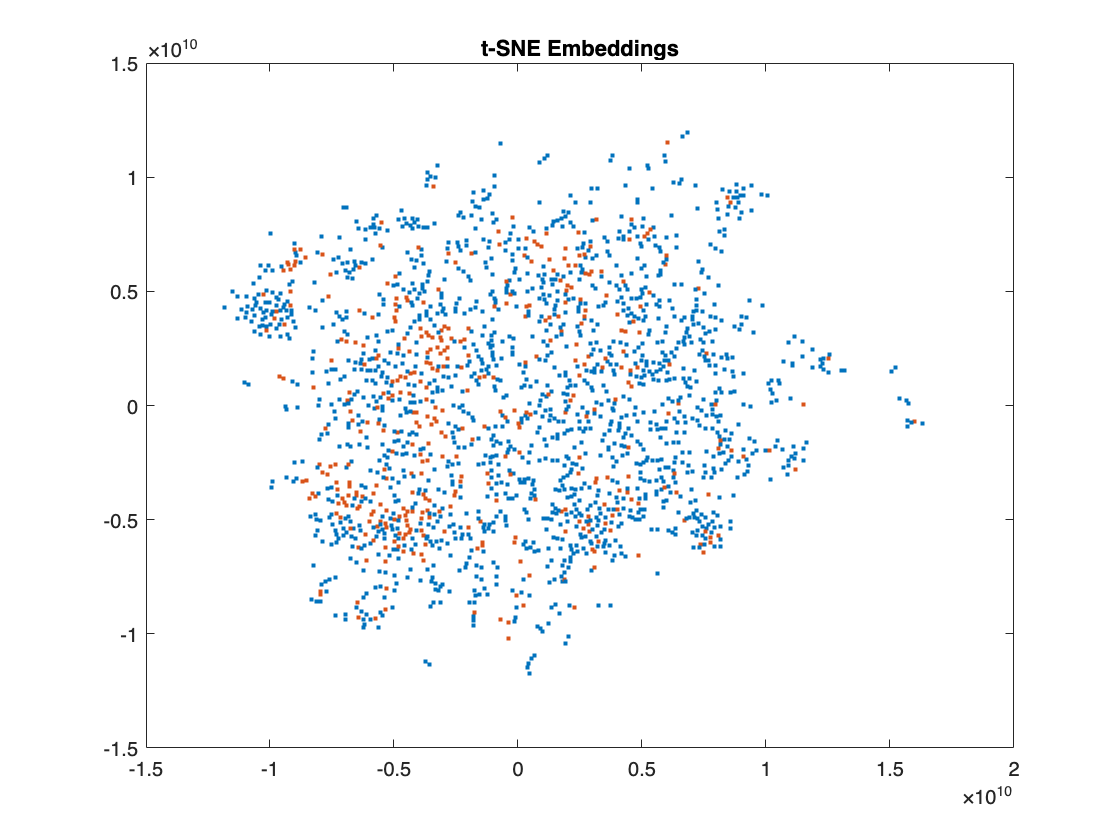

Y = tsne(unlabeledData, Distance="cosine");

figure;
textscatter(Y,data.text,ColorData=labels,TextDensityPercentage=0);
title("t-SNE Embeddings");

clear Y;

separabilityindex(unlabeledData, labels, Distance="cosine")

ans = 0.7320

## Computation

alpha = 0.7;
% kModel = AutoRbfKernel(centredData);
kModel = AutoSphereRbfKernel(unlabeledData);

AutoSphereRbfKernel: Sigma = 1.34891977778247


poc = kMRCD(kModel); 
% solution = poc.runAlgorithm(centredData, alpha);
solution = poc.runAlgorithm(unlabeledData, alpha);

SDO: 2.5852 sec
SpatialMedian: 1.6595 sec
SSCM: 4.9555 sec
Running C-Steps for SDO...
Convergence at iteration 1, SDO
Running C-Steps for SpatialMedian...
Convergence at iteration 1, SpatialMedian
Running C-Steps for SSCM...
Convergence at iteration 1, SSCM
-> Best estimator is SSCM


## Evaluation

hSubset = data(solution.hsubsetIndices, :);

groupcounts(hSubset, "label_text")

ans = 2×3 table
    label_text    GroupCount    Percent
    __________    __________    _______

    not toxic        1105       78.929 
    toxic             295       21.071 


outliers = data(solution.flaggedOutlierIndices, :);

groupcounts(outliers, "label_text")

ans = 2×3 table
    label_text    GroupCount    Percent
    __________    __________    _______

    not toxic        496        82.529 
    toxic            105        17.471 


### Confusion Matrix

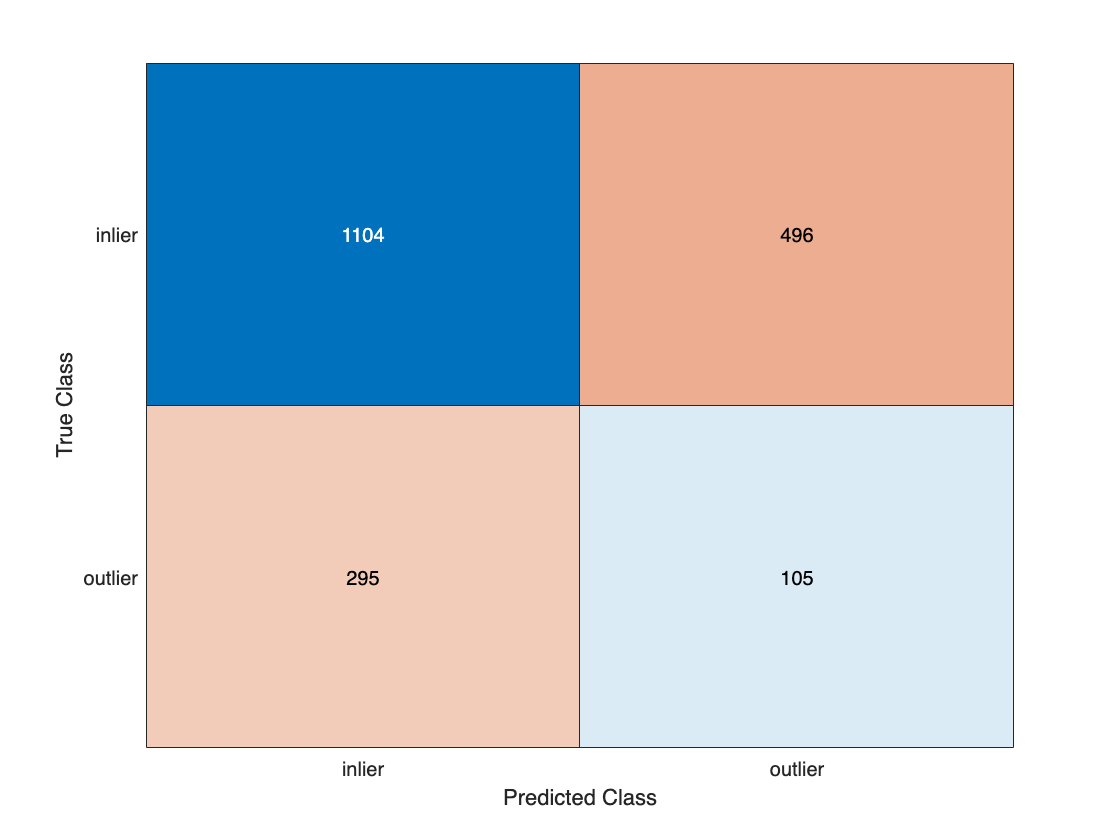

grouphat = categorical(repmat("inlier", size(labels)), categories(labels));
grouphat(solution.flaggedOutlierIndices) = "outlier";

cm = confusionmat(labels,grouphat, Order={'outlier' 'inlier'});
figure;
confusionchart(cm, {'outlier' 'inlier'});

struct2table(confusionstats(cm))

ans = 1×5 table
    accuracy    precision    sensitivity    specificity    f1Score
    ________    _________    ___________    ___________    _______

     0.6045      0.17471       0.2625          0.69        0.20979


### Mahalanobis Distances

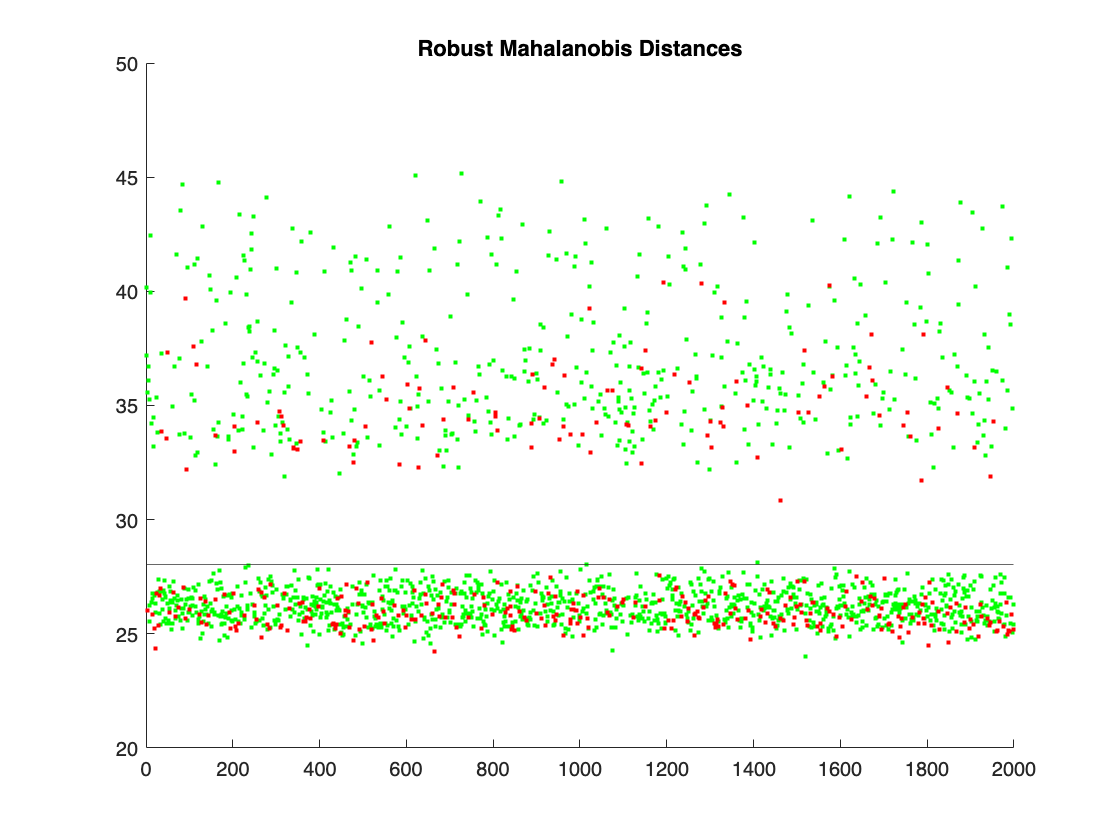

figure;
mahalchart(labels, solution.rd, solution.cutoff);

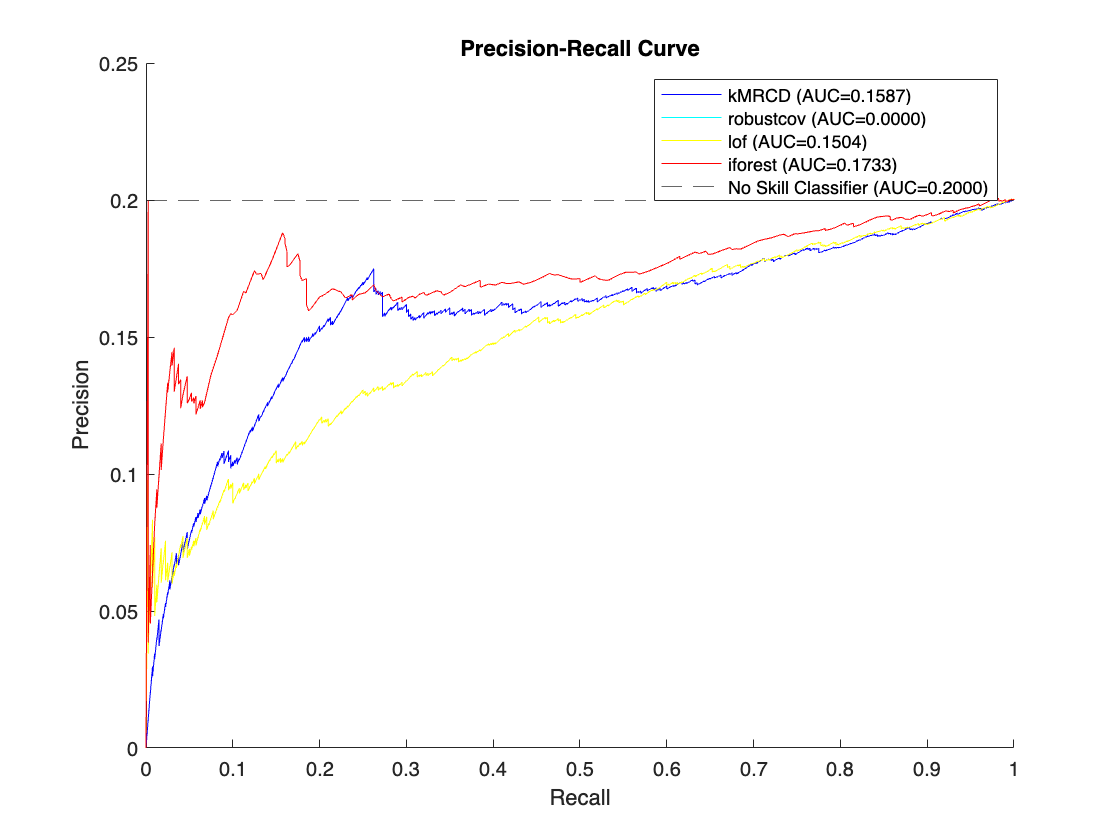

robustcov: 0.0900 sec
lof: 0.4422 sec
iforest: 0.7052 sec


ans = 4×6 table
                 accuracy    precision    sensitivity    specificity    f1Score     aucpr 
                 ________    _________    ___________    ___________    _______    _______

    kMRCD         0.6045      0.17471       0.2625            0.69      0.20979     0.1587
    robustcov        0.8          NaN            0               1            0          0
    lof            0.563        0.105       0.1575         0.66438        0.126    0.15038
    iforest        0.602      0.16554        0.245         0.69125      0.19758    0.17329


figure;
evaluation(unlabeledData, labels, alpha, solution)

% objectiveplot(poc, centredData);
% objectiveplot(poc, unlabeledData);